# Práctica 1 - Visión por Computador

**Juan Carlos Soriano (1493037) - Jorge Giménez Pérez (1493035)**

### Tarea 1 - Cargar el dataset y dividirlo en dos partes iguales, una para modelar el fondo y otra para detectar

Vamos a usar las imágenes de la carpeta input que van desde la *in001051.jpg* hasta la *in001350.jpg*. Las 150 primeras son para entrenar:

dataset_base_path = '../data/';
images_sizes = [240, 320];

first_image_n = 1050;
last_image_n = 1349;

all_images = zeros(images_sizes(1), images_sizes(2), 300);

for i=first_image_n:last_image_n
    image_path = dataset_base_path + "input/in00" + i + ".jpg";
    all_images(:,:,(i-first_image_n)+1) = rgb2gray(imread(image_path));
end

Mostramos una images cualquiera para ver que todo se ha cargado correctamente en la matriz:

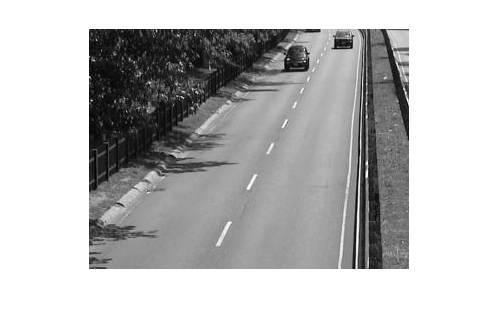

imshow(all_images(:,:,201), [])

Ahora separamos el dataset en test y train:

train_images = all_images(:,:,1:150);
test_images = all_images(:,:,151:300);

### Tarea 2 - Calcular la media y la desviación estándar

Queremos obtener dos matrices. La primera será una que contenga el valor medio de cada pixel de las imágenes de *train* y la segunda será la desviación estándar de cada uno de los píxeles de las imágenes de *train*. Por lo tanto esperamos 2 matrices com medidas 240x320:

training_mean = sum(train_images,3)/150;

Visualizamos que el resultado obtenido tiene sentido:

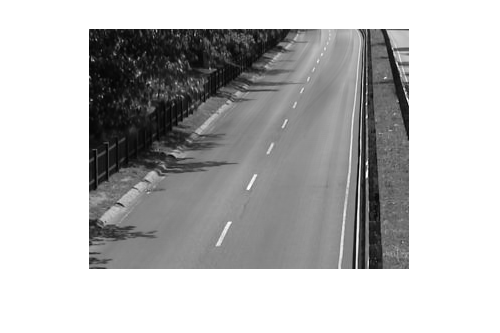

imshow(training_mean, [])


training_std_dev = sqrt(sum(power(train_images -  training_mean, 2), 3)/150);

Visualizamos que el resultado obtenido tiene sentido:

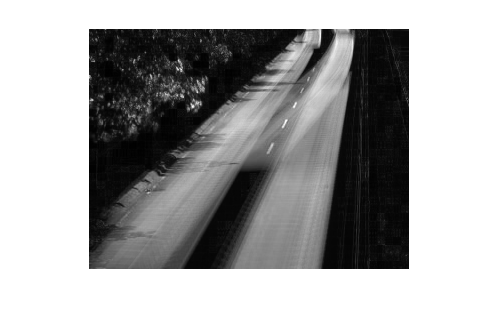

imshow(training_std_dev, [])

### Tarea 3 - Segmentar los coches restando el modelo de fondo

subtracted = test_images - training_mean;
subtracted = subtracted < 0.0001;

Comprobamos que el resultado obtenido tiene sentido:

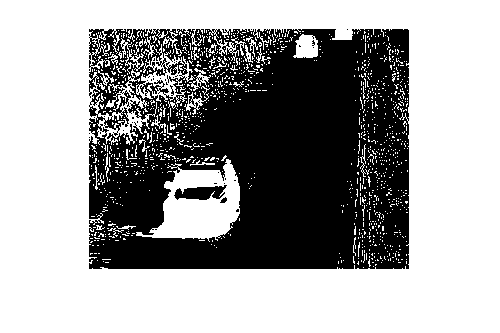

imshow(subtracted(:,:,21), [])